气动双座调节阀  确定额定流量系数C100，阀座直径dg和公称直径Dg，条件如下:

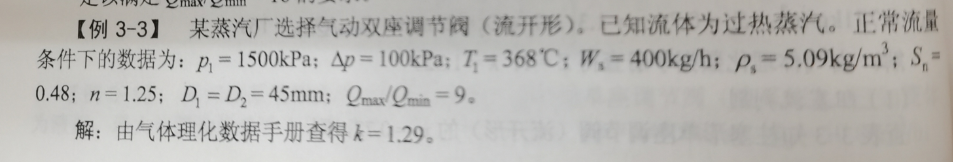

%定义计算蒸汽介质C值所需要的数据
Q_max_min = 10;
p1 = 1500;
delta_p = 100;
T1 = 368;
Ws = 400;
rhos = 5.09;
Sn = 0.48;
n=1.25;
D1 =45;
D2 =45;
k = 1.29

k = 1.2900

xT = 0.7 %双座调节阀参数

xT = 0.7000

MAX = 0 ;
% 以上数据若为最大（正常）流量状态的值，MAX = 1（0）

%阻塞流判别
FK= k/1.4;
x = delta_p / p1;
if (x<FK*xT)
    Y = 1-x/(3*FK*xT);
    C = Ws*sqrt(1/(x*p1*rhos))/(3.16*Y); %非阻塞流
else
    C = Ws*sqrt(1/(k*xT*p1*rhos))/1.78;
end

%计算Cmax值
if(MAX == 0 )
    Smax = 1-n^2*(1-Sn);
    m = n*sqrt(Sn/Smax);
    Cmax = m*C;
else
    Cmax = C;
end

a = 1;
while(a == 1)
    %针对双座阀，初选额定流量系数
    if(Cmax<8);disp('双座阀不满足要求，建议改用单座阀'),end 
    if(8<=Cmax && Cmax<10);C100=10;dg=25;Dg=25;end 
    if(10<=Cmax && Cmax<16);C100=16;dg=32;Dg=32;end 
    if(16<=Cmax && Cmax<25);C100=25;dg=40;Dg=40;end 
    if(25<=Cmax && Cmax<40);C100=40;dg=50;Dg=50;end 
    if(40<=Cmax && Cmax<63);C100=63;dg=60;Dg=65;end 
    if(63<=Cmax && Cmax<100);C100=100;dg=80;Dg=80;end 
    if(100<=Cmax && Cmax<160); C100=160;dg=100;Dg=100;end
    if(160<=Cmax && Cmax<250);C100=250;dg=125;Dg=125;end 
    if(250<=Cmax && Cmax<400);C100=400;dg=150;Dg=150;end 
    if(400<=Cmax && Cmax<=630); C100=630;dg=200;Dg=200;end 
    if(630<=Cmax && Cmax<1000);C100=1000;dg=250;Dg=250;end 
    if(1000<=Cmax && Cmax<=1600);C100=1600;dg=300;Dg=300;end
    if(Cmax>1600);disp('直通单、双座阀均不满足要求，建议改用其他阀');end
    
    %管件形状修正
    if (D1/Dg<1.5)
        break;
    else
        
        Fp = input('需要进行管件形状修正，请输入修正系数Fp =')

        Cmax = Cmax/Fp;
    end
end 

Cmax,C100,dg,Dg   %显示最终选定的参数

Cmax = 11.6217

C100 = 16

dg = 32

Dg = 32